clc; close all;
k = 4;
d = 30;
n = 5;
m = 1e6;

hmm_options.epsilon = 1/10;
hmm_options.method = "random";
hmm_options.distribution = 'Normal';

cpd_options.maxIter = 2500;
cpd_options.tol = 1e-14;
cpd_options.th_relerr = 1e-7;
cpd_options.epsilon = 1/10;

alpha = 0.05;
rho = 0.85;

Nruns = 10;
ps = 1;

UncoupledCost = zeros(3, Nruns);
CoupledCost = zeros(3, Nruns);

T_hats = cell(n,1);
O_hats = cell(n,1);

P3 = cell(n,1);
P_True = cell(n,1);



for j = progress(1:Nruns)

    [T, Os, pi, ~, ~] = generateHMM(k, d, n, hmm_options);

    [seq, ~] = generate_multivariate_hmm_sequence(T, Os, pi, m);

    
    for ii = 1:n
        U = {};
        U{1} = (Os{ii} * diag(pi) * T' / diag(T * pi'));
        U{2} = Os{ii};
        U{3} = (Os{ii} * T);
        P_True{ii} = cpdgen(U)./sum(cpdgen(U), 'all');

        P3{ii} = ProbabilityTensorGenerate(seq(ii, :), 3, d);
    end



    T_hat = zeros(k, k);
    for ii = 1:n
        [A, B, C, ~, ~] = cpd_als_3d(P3{ii}, k, cpd_options);
        O_hat = Stochasticize(B);
        T_hats{ii} = Stochasticize(pinv(Stochasticize(B)) * Stochasticize(C));
    
        Pbest = PermutationFit(T, T_hats{ii}, true);
        T_hats{ii} = Pbest * T_hats{ii} * Pbest';
        T_hat = T_hat + (1/n) * T_hats{ii};
    
        O_hats{ii} = O_hat * Pbest';

        uncoupledTensor = cpdgen({A, B, C}) ./ sum(cpdgen({Stochasticize(A), Stochasticize(B), Stochasticize(C)}), 'all');

        UncoupledCost(1, j) = UncoupledCost(1, j) + (1/n) * norm(P_True{ii} - uncoupledTensor, 'fro');
        UncoupledCost(2, j) = UncoupledCost(2, j) + (1/n) * norm(P3{ii} - uncoupledTensor, 'fro');
    end

    UncoupledCost(3, j) = HMMError(T, Os, T_hat, O_hats, false);

   
    % Coupled CPD

    [T_hat, O_hats, ~, output] = multivariate_coupled_cpd_2(P3, k, d, n, alpha, rho, cpd_options);
    pi_hat = findStationaryDistribution(T_hat')';
    [T_hat, O_hats, ~] = remove_hmm_permutation_transition(T, T_hat, O_hats, pi_hat);

    for ii = 1:n

        CoupledCost(1, j) = CoupledCost(1, j) + (1/n) * norm(P_True{ii} - output.Ps{ii}, 'fro');
        CoupledCost(2, j) = CoupledCost(2, j) + (1/n) * norm(P3{ii} - output.Ps{ii}, 'fro');
    end

    CoupledCost(3, j) = HMMError(T, Os, T_hat, O_hats, false);


end

Processing:  000%  |                                        | 0/10it [00:00:00<Inf:NaN:NaN, Inf it/s]



% save("PerformanceTests/TensorMethodComparison", "UncoupledCost", "CoupledCost", "Nruns");


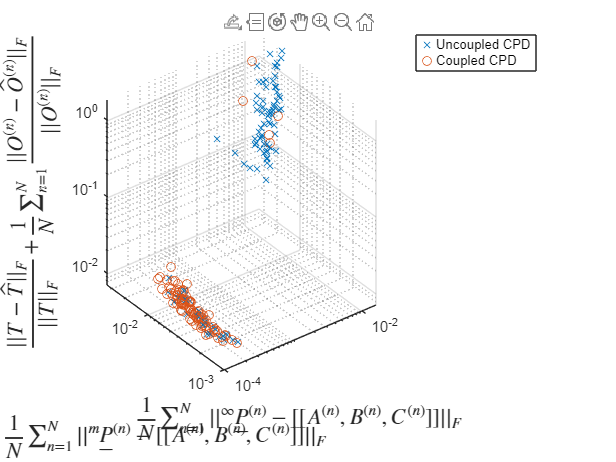


load("PerformanceTests/TensorMethodComparison");

size = 50;
Fontsize = 15;

figure();
scatter3(UncoupledCost(1, :), UncoupledCost(2, :), UncoupledCost(3, :),  "x"); hold on;
scatter3(CoupledCost(1, :), CoupledCost(2, :), CoupledCost(3, :), "o"); hold on;
set(gca,'Xscale','log','Zscale','log','Yscale','log');
legend("Uncoupled CPD", "Coupled CPD"); grid on;
xlabel("$\frac{1}{N}\sum_{n=1}^{N}||^\infty \underline{P}^{(n)} - [[A^{(n)}, B^{(n)} ,C^{(n)}]]||_F$", "Interpreter","latex", FontSize=Fontsize)
ylabel("$\frac{1}{N}\sum_{n=1}^{N}||^m \underline{P}^{(n)} - [[A^{(n)}, B^{(n)} ,C^{(n)}]]||_F$", "Interpreter","latex", FontSize=Fontsize)
zlabel("$\frac{||T - \hat{T}||_F}{||T||_F} + \frac{1}{N} \sum_{n=1}^N \frac{||O^{(n)} - \hat{O}^{(n)}||_F}{||O^{(n)}||_F}$", "Interpreter","latex", FontSize=Fontsize)

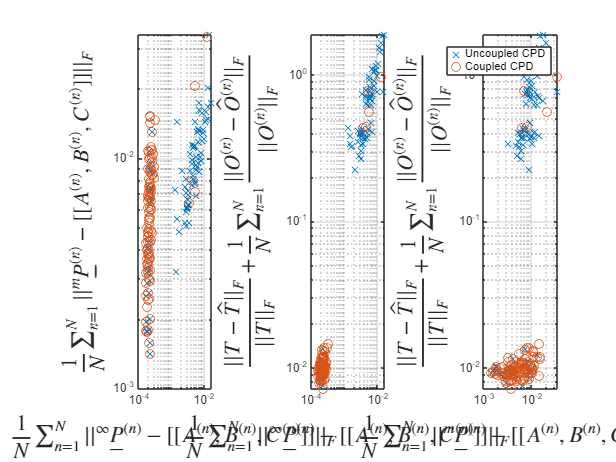



figure();
subplot(1, 3, 1)
loglog(UncoupledCost(1, :),  UncoupledCost(2, :), "x"); hold on;
loglog(CoupledCost(1, :),  CoupledCost(2, :), "o"); hold on;
grid on;
xlabel("$\frac{1}{N}\sum_{n=1}^{N}||^\infty \underline{P}^{(n)} - [[A^{(n)}, B^{(n)} ,C^{(n)}]]||_F$", "Interpreter","latex", FontSize=Fontsize)
ylabel("$\frac{1}{N}\sum_{n=1}^{N}||^m \underline{P}^{(n)} - [[A^{(n)}, B^{(n)} ,C^{(n)}]]||_F$", "Interpreter","latex", FontSize=Fontsize)


subplot(1, 3, 2)
loglog(UncoupledCost(1, :),  UncoupledCost(3, :), "x"); hold on;
loglog(CoupledCost(1, :),  CoupledCost(3, :), "o"); hold on;
grid on;
xlabel("$\frac{1}{N}\sum_{n=1}^{N}||^\infty \underline{P}^{(n)} - [[A^{(n)}, B^{(n)} ,C^{(n)}]]||_F$", "Interpreter","latex", FontSize=Fontsize)
ylabel("$\frac{||T - \hat{T}||_F}{||T||_F} + \frac{1}{N} \sum_{n=1}^N \frac{||O^{(n)} - \hat{O}^{(n)}||_F}{||O^{(n)}||_F}$", "Interpreter","latex", FontSize=Fontsize)

subplot(1, 3, 3)
loglog(UncoupledCost(2, :),  UncoupledCost(3, :),  "x"); hold on;
loglog(CoupledCost(2, :),  CoupledCost(3, :), "o"); hold on;
legend("Uncoupled CPD", "Coupled CPD"); grid on;
xlabel("$\frac{1}{N}\sum_{n=1}^{N}||^m \underline{P}^{(n)} - [[A^{(n)}, B^{(n)} ,C^{(n)}]]||_F$", "Interpreter","latex", FontSize=Fontsize)
ylabel("$\frac{||T - \hat{T}||_F}{||T||_F} + \frac{1}{N} \sum_{n=1}^N \frac{||O^{(n)} - \hat{O}^{(n)}||_F}{||O^{(n)}||_F}$", "Interpreter","latex", FontSize=Fontsize)